# **Einfluss von Nullstellen / Influence of zeros**

## Definition von Eigenfrequenz & Dämpfung sovie Nullstelle von PDT2 Glied

Definition of natural frequency & damping and zero of PDT2 element

clear all
% Nullstellenzeitkonstante / Time constant of zero
%Tv = [0,.5:0.5:2,4];      % 'stabile' Nullstellen' / stable zero
Tv = -[0,.5:0.5:2,4];      % 'instabile' bzw RHE Nullstellen / 'unstable' RHP zero


% Freqeunz und Dämpfung / Frequency and damping

w0 = 1; D = 0.7;

s = tf('s');

for i = 1:length(Tv)
    G(:,:,i)  = (Tv(i)*s+1)/(w0^-2*s^2 + 2*D/w0*s + 1);
    mu = zero(G(:,:,i));
    
    if ~isempty(mu)
        disp(['Tv = ',num2str(Tv(i)), ' zero at mu = ', num2str(mu)])
    else
        disp(['Tv = ',num2str(Tv(i)), ' -> G(s) has no zeros'])
    end
    
end

Tv = 0 -> G(s) has no zeros


Tv = -0.5 zero at mu = 2
Tv = -1 zero at mu = 1
Tv = -1.5 zero at mu = 0.66667
Tv = -2 zero at mu = 0.5
Tv = -4 zero at mu = 0.25


## PN Diagramm / PZ Map

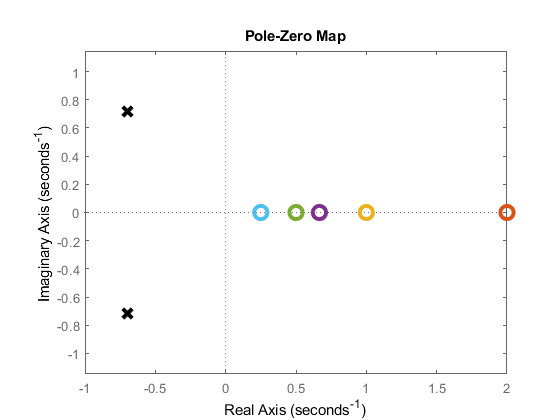

figure(1); 
for i = 1:length(Tv)
    pzmap(G(:,:,i)); hold on
    % Set Zero Style
    h1 = gca;
    h1.Children(1).Children(1).LineWidth =3;
    h1.Children(1).Children(1).MarkerSize =10;
    color(i,:) = h1.Children(1).Children(1).Color;
end
    % Set Pole Style
    h1.Children(1).Children(2).MarkerSize =10;
    h1.Children(1).Children(2).LineWidth =3;
    h1.Children(1).Children(2).Color =[0 0 0];
axis equal;

## Sprungantwort / Step response

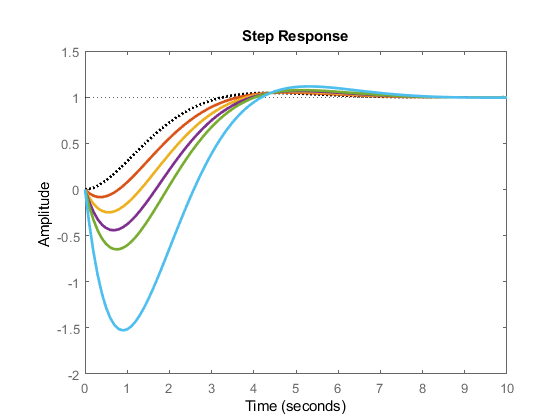

figure(2); hold on;
for i = 1:length(Tv)
    if i==1
    step(G(:,:,i),10,'black:'); 
    else
      step(G(:,:,i),10);
      h2.Children(1).Children(2).Color =color(i,:);
    end
           
    % Increase Linewidth:
    h2 = gca; h2.Children(1).Children(2).LineWidth =2;
    
end